# Conditional Generative Adversarial Network (CGAN) for Hand-Written Digits Generation

This example shows how to train a conditional generative adversarial network (CGAN) to generate digit images.

This demo was created based on the Matlab official document entitled Train Conditional Generative Adversarial Network (CGAN)

[1] [https://jp.mathworks.com/help/deeplearning/ug/train-conditional-generative-adversarial-network.html]](https://jp.mathworks.com/help/deeplearning/ug/train-conditional-generative-adversarial-network.html])

Conditinal Generative Adversarial Network (CGAN) was proposed in the paper

[https://arxiv.org/pdf/1411.1784.pdf](https://arxiv.org/pdf/1411.1784.pdf)

[2] Mirza M, Osindero S. Conditional generative adversarial nets. arXiv preprint arXiv:1411.1784. 2014 Nov 6.

This livescript was made with the references below. 

[3] 山下隆義、イラストで学ぶ　ディープラーニング　改訂第2版、ＫＳ情報科学専門書、2018年

## Load Training Data

Load the hand-written dataset into a variable called `imds`. 

clear;clc;close all force
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', 'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, 'IncludeSubfolders',true,'LabelSource','foldernames');

Augment the data to include random horizontal flipping and resize the images to have size 32-by-32. You can customize the augmentation method. For its detail, pls refer to [https://jp.mathworks.com/help/deeplearning/ug/image-augmentation-using-image-processing-toolbox.html](https://jp.mathworks.com/help/deeplearning/ug/image-augmentation-using-image-processing-toolbox.html)

augmenter = imageDataAugmenter('RandXReflection',false);
augimds = augmentedImageDatastore([32 32],imds,'DataAugmentation',augmenter);

## Define Generator Network: Overview

The generator for CGAN requires two inputs: noise input and label input. Those inputs are up-sampled into image-like shape for the further processing. Then, define the following two-input network, which generates images given 1-by-1-by-100 arrays of random values and corresponding labels:

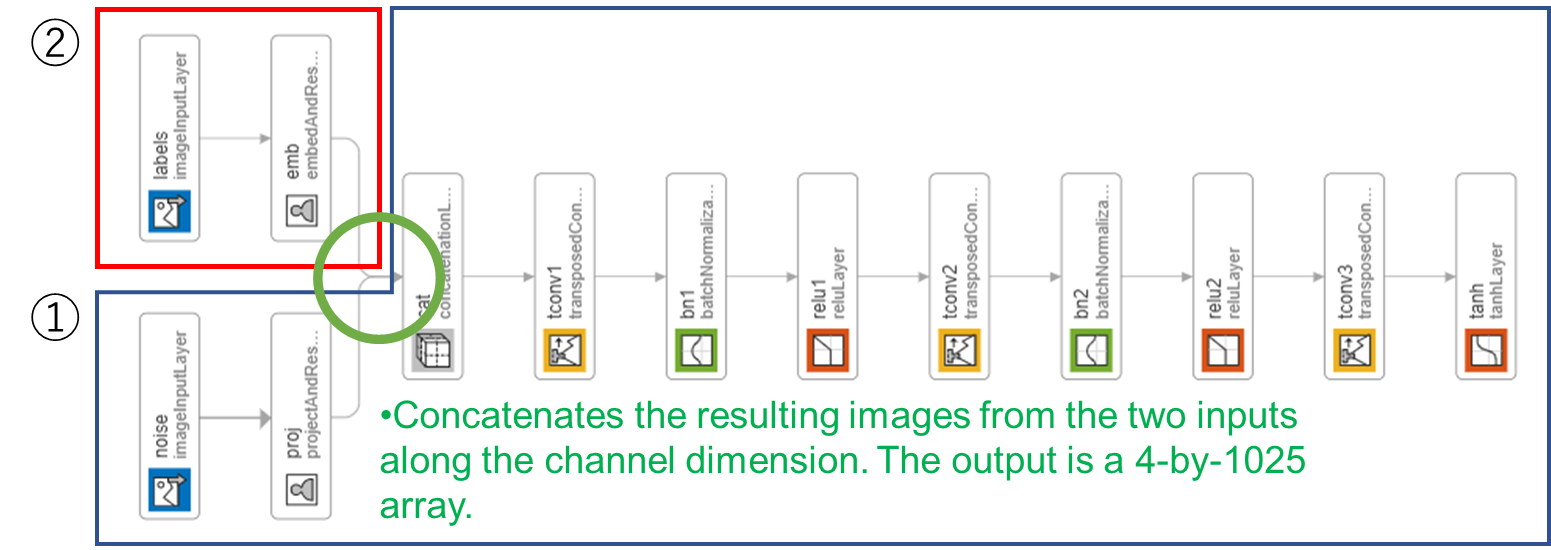

## Generator 1 : from the label input

To project and reshape the noise input, use the custom layer [`projectAndReshapeLayer`](matlab:edit(fullfile(matlabroot,'examples','nnet','main','projectAndReshapeLayer.m'))), attached to this example as a supporting file. The `projectAndReshapeLayer` object upscales the input using a fully connected operation and reshapes the output to the specified size. 

The category (class) information was converted into "one-hot vector", where the index corresponding to the target image is one. Please see the figure below. 

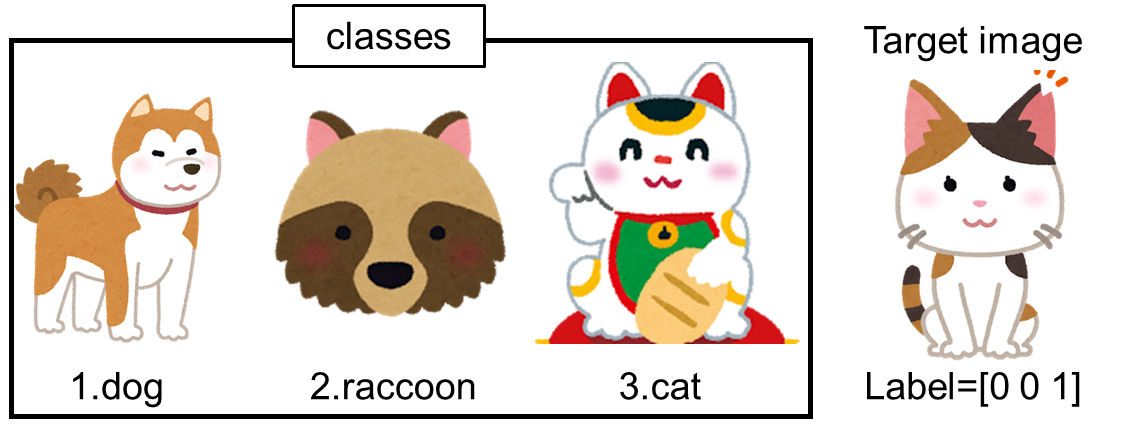

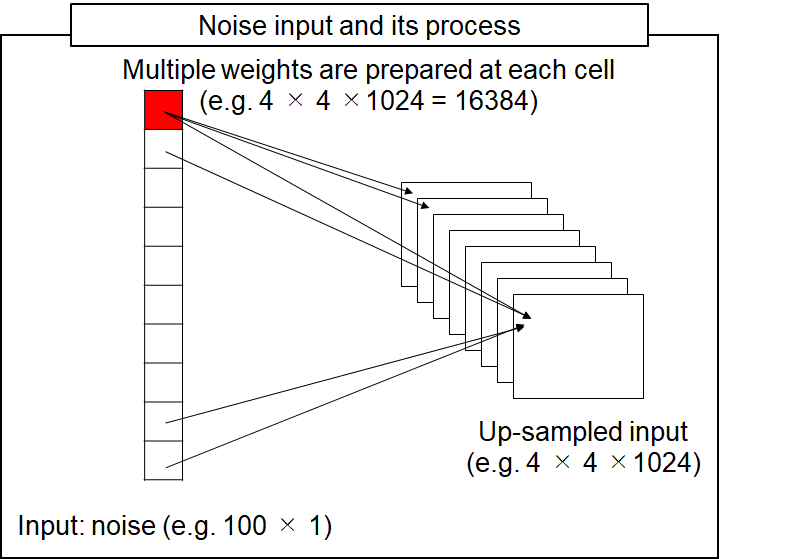

numLatentInputs = 100; % the dimension of the random noise to synthesize the image
numFilters = 100;% the number of convolutional filters in the generator
numClasses=10; % the number of class to generate
filterSize = 5; % the filter size of the convolutional layer
projectionSize = [4 4 1024];%the size to up-sample from the noise input

layersGenerator = [
    imageInputLayer([1 1 numLatentInputs],'Normalization','none','Name','noise')
    projectAndReshapeLayer(projectionSize,numLatentInputs,'proj');
    concatenationLayer(3,2,'Name','cat')
    transposedConv2dLayer(filterSize,2*numFilters,'Name','tconv1')
    batchNormalizationLayer('Name','bn1')
    reluLayer('Name','relu1')%the activation layers other than last one are "relu"
    transposedConv2dLayer(filterSize,numFilters,'Stride',2,'Cropping','same','Name','tconv2')
    batchNormalizationLayer('Name','bn2')
    reluLayer('Name','relu2') %the activation layers other than last one are "relu"
    transposedConv2dLayer(filterSize,1,'Stride',2,'Cropping','same','Name','tconv3')% the value "1" corresponds to number of channel (RGB).
   % As this demo uses grayscale image, the number of channel of the final output should be 1.      
    tanhLayer('Name','tanh')]; %only the final activation layer is "tanh" while the others are "relu"

次を使用中: projectAndReshapeLayer
位置 2 の引数が無効です。 名前が必要です。

## Generator 2 : from the label input

- The label input was converted into embedding vectors and reshaped to a 4-by-4 as shown below.

- To embed and reshape the label input, use the custom layer [`embedAndReshapeLayer`](matlab:edit(fullfile(matlabroot,'examples','nnet','main','embedAndReshapeLayer.m'))), attached to this example as a supporting file. 

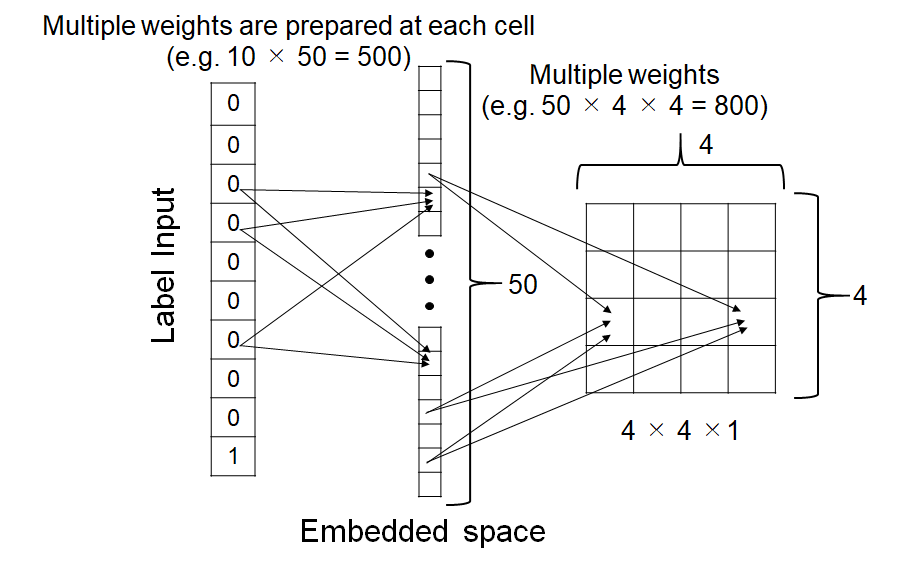

lgraphGenerator = layerGraph(layersGenerator);
embeddingDimension = 50;
layers = [
    imageInputLayer([1 1],'Name','labels','Normalization','none')
    embedAndReshapeLayer(projectionSize(1:2),embeddingDimension,numClasses,'emb')];

## Connect the two-inputs in the generator

- Connect the generator 1 and generator 2 as built above by using `addLayers` and `connectLayers` function. 

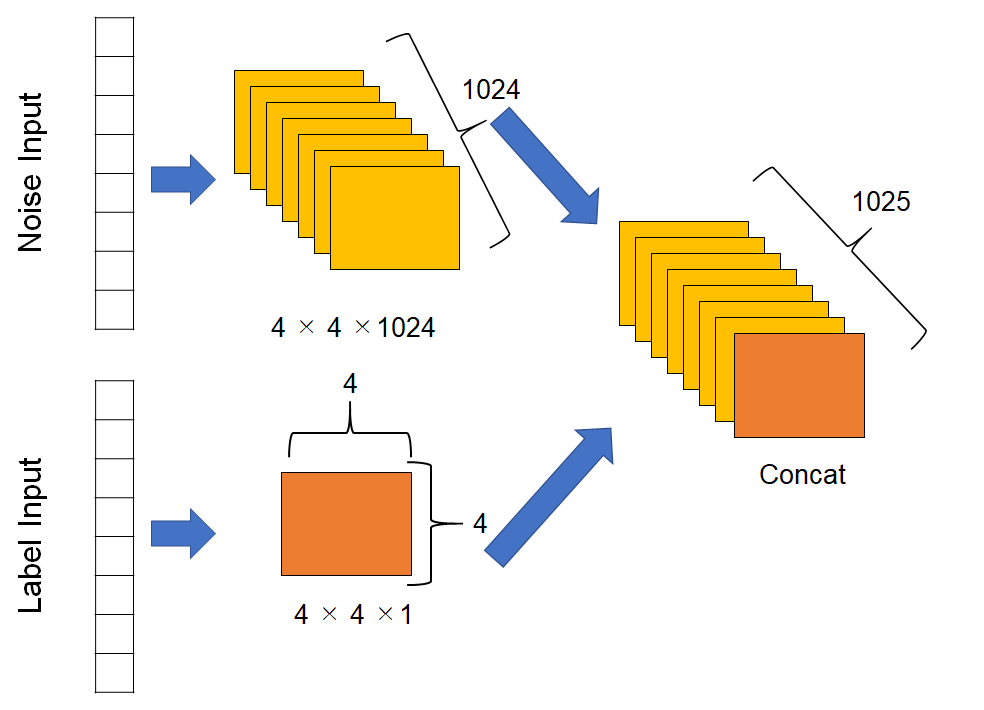

lgraphGenerator = addLayers(lgraphGenerator,layers);
lgraphGenerator = connectLayers(lgraphGenerator,'emb','cat/in2');

To train the network with a custom training loop and enable automatic differentiation, convert the layer graph to a `dlnetwork` object.

dlnetGenerator = dlnetwork(lgraphGenerator)

## Define discriminator Network: Overview

Define the following two-input network, which classifies real and generated 32-by-32 images given a set of images and the corresponding labels. Create a network that takes as input 32-by-32-by-1 images and the corresponding labels and outputs a scalar prediction score using a series of convolution layers with batch normalization and leaky ReLU layers. Add noise to the input images using dropout.

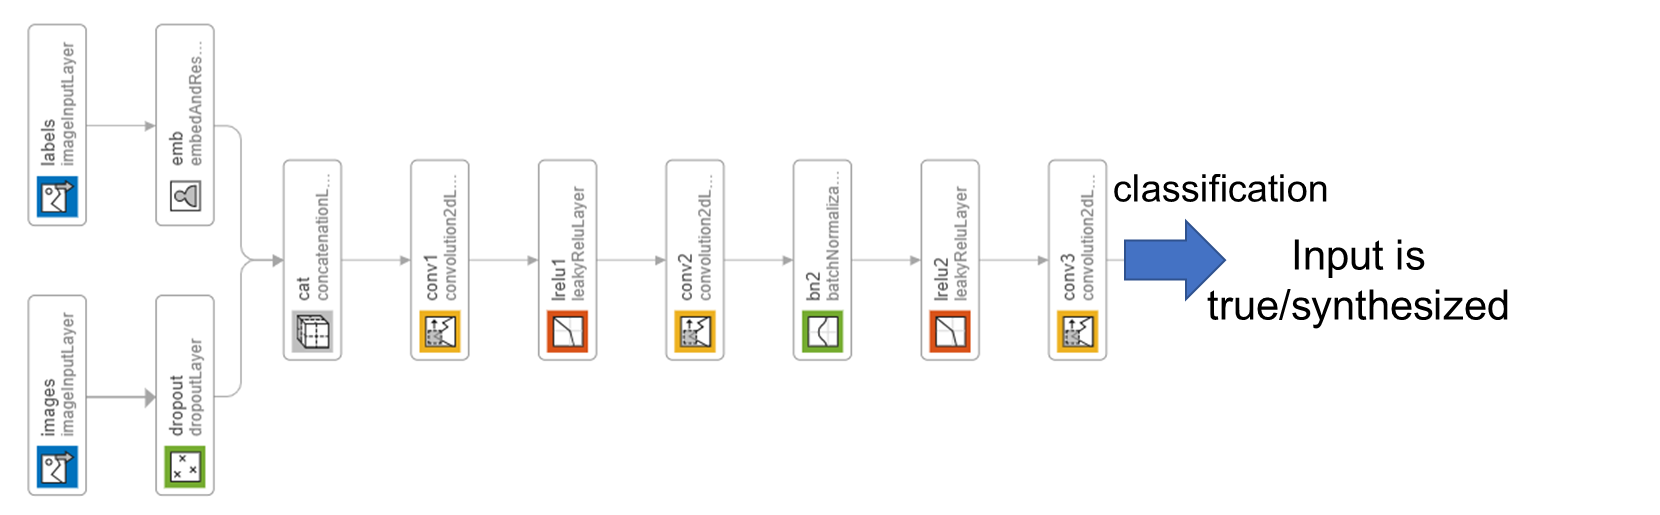

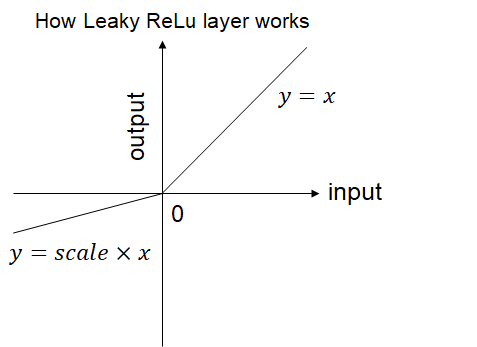

dropoutProb = 0.25;% After the input, dropout layer was put.
% For the dropout layer, specify a dropout probability of 0.25.
numFilters = 32; % the number of filters for the convolution
scale = 0.2;% the variable (scale) for Leaky ReLu Layer

inputSize = [32 32 1];% input size of the input image
filterSize = 3;% the size of convolutional filter

## Define discriminator

- The detail of the descriminator is specified in this section. 

- The stride of the convlutional layer is 2. 

- For the detail of each layer, please check the document below.

[https://jp.mathworks.com/help/deeplearning/ug/define-custom-training-loops-loss-functions-and-networks.html](https://jp.mathworks.com/help/deeplearning/ug/define-custom-training-loops-loss-functions-and-networks.html)

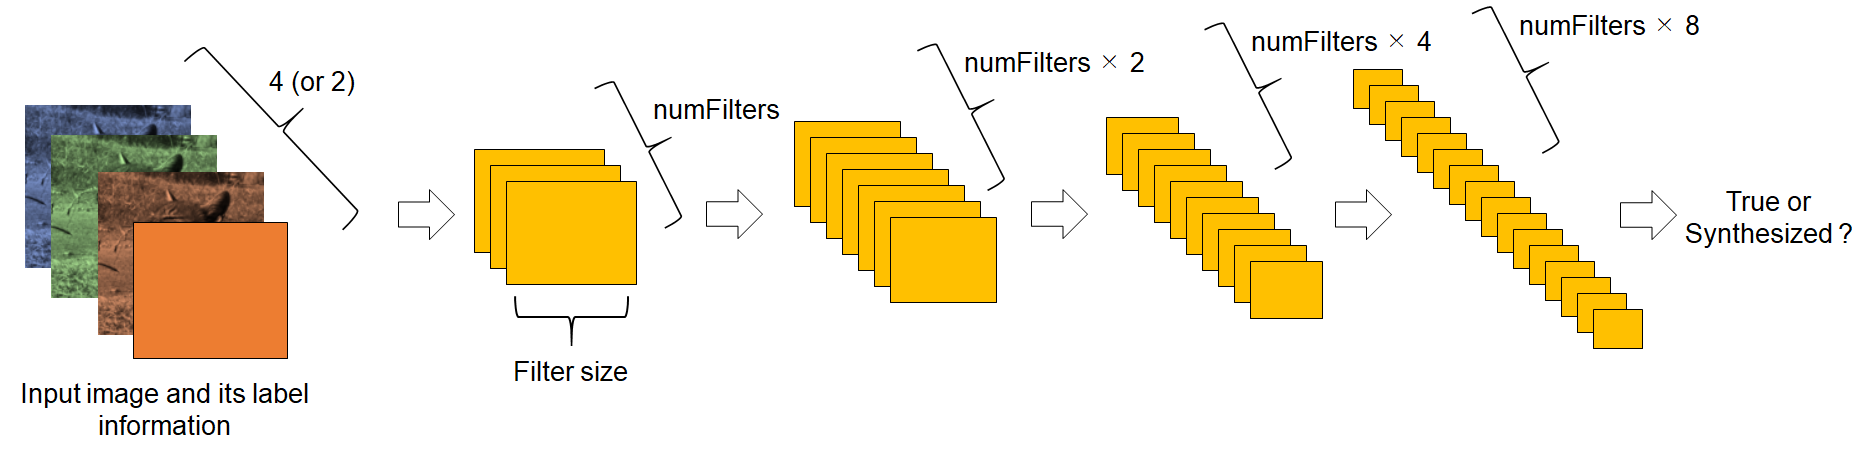

layersDiscriminator = [
    imageInputLayer(inputSize,'Normalization','none','Name','images')
    dropoutLayer(dropoutProb,'Name','dropout')
    concatenationLayer(3,2,'Name','cat')
    convolution2dLayer(filterSize,numFilters,'Stride',2,'Padding','same','Name','conv1')
    leakyReluLayer(scale,'Name','lrelu1')
    convolution2dLayer(filterSize,2*numFilters,'Stride',2,'Padding','same','Name','conv2')
    batchNormalizationLayer('Name','bn2')
    leakyReluLayer(scale,'Name','lrelu2')
    convolution2dLayer(filterSize,4*numFilters,'Stride',2,'Padding','same','Name','conv3')
    batchNormalizationLayer('Name','bn3')
    leakyReluLayer(scale,'Name','lrelu3')
    convolution2dLayer(filterSize,8*numFilters,'Stride',2,'Padding','same','Name','conv4')
    batchNormalizationLayer('Name','bn4')
    leakyReluLayer(scale,'Name','lrelu4')
    convolution2dLayer(2,1,'Name','conv5')];

lgraphDiscriminator = layerGraph(layersDiscriminator);

## Connect the stream from image input and the label information

- To perform the operation in the last section, the two stream from image input and label input were connected. 

- Here, the network for the operation is ready.  

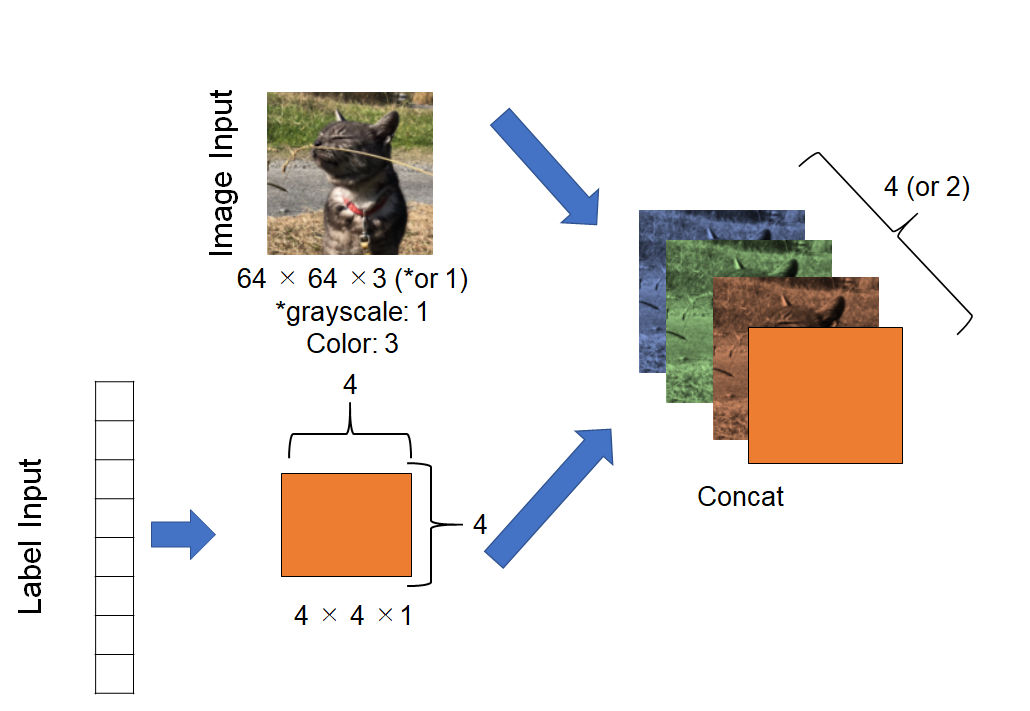

layers = [
    imageInputLayer([1 1],'Name','labels','Normalization','none')
    embedAndReshapeLayer(inputSize,embeddingDimension,numClasses,'emb')];

lgraphDiscriminator = addLayers(lgraphDiscriminator,layers);
lgraphDiscriminator = connectLayers(lgraphDiscriminator,'emb','cat/in2');

To train the network with a custom training loop and enable automatic differentiation, convert the layer graph to a `dlnetwork` object.

dlnetDiscriminator = dlnetwork(lgraphDiscriminator)

## Define Model Gradients and Loss Functions

Create the function `modelGradients`, listed in the Model Gradients Function section of the example, which takes as input the generator and discriminator networks, a mini-batch of input data, and an array of random values, and returns the gradients of the loss with respect to the learnable parameters in the networks and an array of generated images.

## Specify Training Options

numEpochs = 5; % epoch 
miniBatchSize = 128; % mini batch size
augimds.MiniBatchSize = miniBatchSize;
learnRate = 0.0002; %  base learning rate (parameter) in adam 
gradientDecayFactor = 0.5;% gradient decay factor
squaredGradientDecayFactor = 0.999; % squared gradient factor
executionEnvironment = "auto";
validationFrequency = 50;

If the discriminator learns to discriminate between real and generated images too quickly, then the generator may fail to train. To better balance the learning of the discriminator and the generator, randomly flip the labels of a proportion of the real images. Specify a flip factor of 0.5. 

flipFactor = 0.5;

## Preparation for the training

% specify the parameters in the ADAM optimizer
velocityDiscriminator = []; 
trailingAvgGenerator = [];
trailingAvgSqGenerator = [];
trailingAvgDiscriminator = [];
trailingAvgSqDiscriminator = [];
% create a figure to monitor the progress
f = figure;
f.Position(3) = 2*f.Position(3);
imageAxes = subplot(1,2,1);
scoreAxes = subplot(1,2,2);
lineScoreGenerator = animatedline(scoreAxes,'Color',[0 0.447 0.741]); 
lineScoreDiscriminator = animatedline(scoreAxes, 'Color', [0.85 0.325 0.098]);
%Customize the appearance of the plots.
legend('Generator','Discriminator'); 
ylim([0 1])
xlabel("Iteration")
ylabel("Score")
grid on

To monitor training progress, create a held-out batch of 25 1-by-1-by-`numLatentInputs` arrays of random values and a corresponding set of labels 1 through 5 (corresponding to the classes) repeated 5 times, where the labels are in the fourth dimension of the array.

numValidationImagesPerClass = 5;
ZValidation = randn(1,1,numLatentInputs,numValidationImagesPerClass*numClasses,'single');
TValidation = single(repmat(1:numClasses,[1 numValidationImagesPerClass]));
TValidation = permute(TValidation,[1 3 4 2]);%exchange the dimension in the TValidation
% For example, the 2nd dimension goes to 4th dimension

Convert the data to `dlarray` objects and specify the dimension labels `'SSCB'` (spatial, spatial, channel, batch).

dlZValidation = dlarray(ZValidation, 'SSCB');
dlTValidation = dlarray(TValidation, 'SSCB');

For GPU training, convert the data to `gpuArray` objects.

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZValidation = gpuArray(dlZValidation);
    dlTValidation = gpuArray(dlTValidation);
end

Train the GAN. For each epoch, shuffle the data and loop over mini-batches of data.

iteration = 0;
start = tic;
doTraining=1;
if doTraining==1
% Loop over epochs.
for epoch = 1:numEpochs
    
    % Reset and shuffle datastore.
    reset(augimds);
    augimds = shuffle(augimds);
    
    % Loop over mini-batches.
    while hasdata(augimds)
        iteration = iteration + 1;
        
        % Read mini-batch of data and generate latent inputs for the
        % generator network.
        data = read(augimds);
        
        % Ignore last partial mini-batch of epoch.
        if size(data,1) < miniBatchSize
            continue
        end
        
        X = cat(4,data{:,1}{:});
        X = single(X);
        
        T = single(data.response);
        T = permute(T,[2 3 4 1]);
        
        Z = randn(1,1,numLatentInputs,miniBatchSize,'single');
        
        % Rescale the images in the range [-1 1].
        X = rescale(X,-1,1,'InputMin',0,'InputMax',255);
        
        % Convert mini-batch of data to dlarray and specify the dimension labels
        % 'SSCB' (spatial, spatial, channel, batch).
        dlX = dlarray(X, 'SSCB');
        dlZ = dlarray(Z, 'SSCB');
        dlT = dlarray(T, 'SSCB');
        
        % If training on a GPU, then convert data to gpuArray.
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlX = gpuArray(dlX);
            dlZ = gpuArray(dlZ);
            dlT = gpuArray(dlT);
        end
        
        % Evaluate the model gradients and the generator state using
        % dlfeval and the modelGradients function listed at the end of the a
        % example.
        [gradientsGenerator, gradientsDiscriminator, stateGenerator, scoreGenerator, scoreDiscriminator] = ...
            dlfeval(@modelGradients, dlnetGenerator, dlnetDiscriminator, dlX, dlT, dlZ, flipFactor);
        dlnetGenerator.State = stateGenerator;
        
        % Update the discriminator network parameters.
        [dlnetDiscriminator,trailingAvgDiscriminator,trailingAvgSqDiscriminator] = ...
            adamupdate(dlnetDiscriminator, gradientsDiscriminator, ...
            trailingAvgDiscriminator, trailingAvgSqDiscriminator, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);
        
        % Update the generator network parameters.
        [dlnetGenerator,trailingAvgGenerator,trailingAvgSqGenerator] = ...
            adamupdate(dlnetGenerator, gradientsGenerator, ...
            trailingAvgGenerator, trailingAvgSqGenerator, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);
        
        % Every validationFrequency iterations, display batch of generated images using the
        % held-out generator input.
        if mod(iteration,validationFrequency) == 0 || iteration == 1
            
            % Generate images using the held-out generator input.
            dlXGeneratedValidation = predict(dlnetGenerator,dlZValidation,dlTValidation);
            
            % Tile and rescale the images in the range [0 1].
            I = imtile(extractdata(dlXGeneratedValidation), ...
                'GridSize',[numValidationImagesPerClass numClasses]);
            I = rescale(I);
            
            % Display the images.
            subplot(1,2,1);
            image(imageAxes,uint8(I*255))
            colormap(gray)
            xticklabels([]);
            yticklabels([]);
            title("Generated Images");
        end
        
        % Update the scores plot
        subplot(1,2,2)
        addpoints(lineScoreGenerator,iteration,...
            double(gather(extractdata(scoreGenerator))));
        
        addpoints(lineScoreDiscriminator,iteration,...
            double(gather(extractdata(scoreDiscriminator))));
        
        % Update the title with training progress information.
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        title(...
            "Epoch: " + epoch + ", " + ...
            "Iteration: " + iteration + ", " + ...
            "Elapsed: " + string(D))
        
        drawnow
    end
end
else 
    if exist('dlnetGenerator.mat')==7 %training takes some times to run. pls load the pre-trained generator to easily try this demo
        load('dlnetGenerator.mat')
    else
        disp('error: the generator was not found in your directry. if you do not have, pls train the model')
    end
end

Here, the discriminator has learned a strong feature representation that identifies real images among generated images. In turn, the generator has learned a similarly strong feature representation that allows it to generate realistic looking data. Each column corresponds to a single class.

The training plot shows the scores of the generator and discriminator networks. To learn more about how to interpret the network scores, see [Monitor GAN Training Progress and Identify Common Failure Modes](docid:nnet_ug#mw_1e0e9d04-f6fc-4e77-97e7-c6aab7d7e0df).

## Generate New Images

To generate new images of a particular class, use the `predict` function on the generator with a `dlarray` object containing a batch of 1-by-1-by-`numLatentInputs` arrays of random values and an array of labels corresponding to the desired classes. Convert the data to `dlarray` objects and specify the dimension labels `'SSCB'` (spatial, spatial, channel, batch). For GPU prediction, convert the data to `gpuArray`. To display the images together, use the `imtile` function and rescale the images using the `rescale` function.

Create an array of 36 vectors of random values corresponding to the first class.

dispNum=100;
count=1;f=figure;
set(gcf,'visible','on')
filename = 'testAnimated.gif'; 
while count<dispNum
Z = randn(1,1,numLatentInputs,100,'single');
T = repmat(reshape(single(1:10),[1 1 1 10]),[1 1 1 10]);

Convert the data to `dlarray` objects with the dimension labels `'SSCB'` (spatial, spatial, channels, batch).

dlZ = dlarray(Z,'SSCB');
dlT = dlarray(T,'SSCB');

 To generate images using the GPU, also convert the data to `gpuArray` objects.

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZ = gpuArray(dlZ);
    dlT = gpuArray(dlT);
end

Generate images using the `predict` function with the generator network.

dlXGenerated = predict(dlnetGenerator,dlZ,dlT);

Display the generated images in a plot.

I = imtile(extractdata(dlXGenerated));
I = rescale(I);
image(uint8(I*255))
colormap(gray)
% save the generated images into GIF file
frame = getframe(gcf);
[A,map] = rgb2ind(frame.cdata,256);
if count == 1
    imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',.1);
else
    imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',.1);
end
count=count+1;
end

Here, the generator network generates images conditioned on the specified class.

## Model Gradients Function

The function `modelGradients` takes as input the generator and discriminator `dlnetwork` objects `dlnetGenerator` and `dlnetDiscrimintor`, a mini-batch of input data `dlX`, the corresponding labels `dlT`, and an array of random values `dlZ`, and returns the gradients of the loss with respect to the learnable parameters in the networks, the generator state, and the network scores.

If the discriminator learns to discriminate between real and generated images too quickly, then the generator may fail to train. To better balance the learning of the discriminator and the generator, randomly flip the labels of a proportion of the real images.

function [gradientsGenerator, gradientsDiscriminator, stateGenerator, scoreGenerator, scoreDiscriminator] = ...
    modelGradients(dlnetGenerator, dlnetDiscriminator, dlX, dlT, dlZ, flipFactor)

% Calculate the predictions for real data with the discriminator network.
dlYPred = forward(dlnetDiscriminator, dlX, dlT);

% Calculate the predictions for generated data with the discriminator network.
[dlXGenerated,stateGenerator] = forward(dlnetGenerator, dlZ, dlT);
dlYPredGenerated = forward(dlnetDiscriminator, dlXGenerated, dlT);

% Calculate probabilities.
probGenerated = sigmoid(dlYPredGenerated);
probReal = sigmoid(dlYPred);

% Calculate the generator and discriminator scores
scoreGenerator = mean(probGenerated);
scoreDiscriminator = (mean(probReal) + mean(1-probGenerated)) / 2;

% Flip labels.
numObservations = size(dlYPred,4);
idx = randperm(numObservations,floor(flipFactor * numObservations));
probReal(:,:,:,idx) = 1 - probReal(:,:,:,idx);

% Calculate the GAN loss.
[lossGenerator, lossDiscriminator] = ganLoss(probReal, probGenerated);

% For each network, calculate the gradients with respect to the loss.
gradientsGenerator = dlgradient(lossGenerator, dlnetGenerator.Learnables,'RetainData',true);
gradientsDiscriminator = dlgradient(lossDiscriminator, dlnetDiscriminator.Learnables);

end

## GAN Loss Function

The objective of the generator is to generate data that the discriminator classifies as "real". To maximize the probability that images from the generator are classified as real by the discriminator, minimize the negative log likelihood function.

Given the output $Y$ of the discriminator:

- $\hat{Y} =\sigma \left(Y\right)$ is the probability that the input image belongs to the class "real".

- $1-\hat{Y}$ is the probability that the input image belongs to the class "generated".

Note that the sigmoid operation $\sigma$ in the `modelGradients` function. The loss function for the generator is given by

    
$$\textrm{lossGenerator}=-\textrm{mean}\left(\log \left({\hat{Y} }_{\textrm{Generated}} \right)\right),$$


where $\hat{Y}_{Generated}$ contains the discriminator output probabilities for the generated images. 

The objective of the discriminator is to not be "fooled" by the generator. To maximize the probability that the discriminator successfully discriminates between the real and generated images, minimize the sum of the corresponding negative log likelihood functions. The loss function for the discriminator is given by

    
$$\textrm{lossDiscriminator}=-\textrm{mean}\left(\log \left({\hat{Y} }_{\textrm{Real}} \right)\right)-\textrm{mean}\left(\log \left(1-{\hat{Y} }_{\textrm{Generated}} \right)\right),$$


where $\hat{Y}_{Real}$ contains the discriminator output probabilities for the real images. 

function [lossGenerator, lossDiscriminator] = ganLoss(scoresReal,scoresGenerated)

% Calculate losses for the discriminator network.
lossGenerated = -mean(log(1 - scoresGenerated));
lossReal = -mean(log(scoresReal));

% Combine the losses for the discriminator network.
lossDiscriminator = lossReal + lossGenerated;

% Calculate the loss for the generator network.
lossGenerator = -mean(log(scoresGenerated));

end